# MIMO Wireless Communications | Assignment #1

### Q1. Capacity plot for AWGN SISO channel:

%vector of SNR[db] from 0db to 40db with a step size of 5
SNRdb = 0:5:40;

%converting SNR[db] into linear scale.

SNRlinear = 10.^(SNRdb/10);

%calculating capacity.

Capacity = log2(1+SNRlinear);

plot(SNRdb, Capacity);
hold off;

Adding Title and labels to the plot

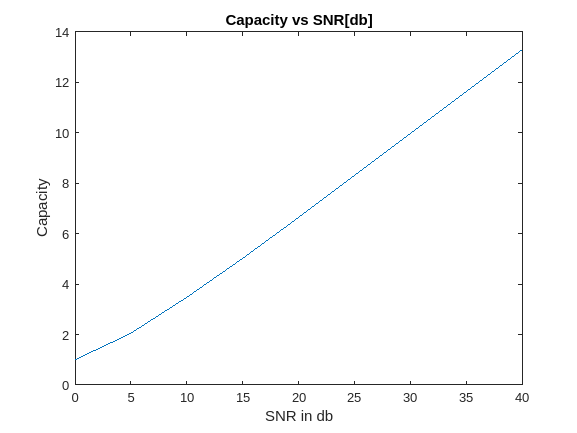

title('Capacity vs SNR[db]')
xlabel('SNR in db')
ylabel('Capacity')

### Q2. Capacity plot for fixed SIMO channel with channel information at both tx and rx:

%number of receivers is 4
nr = 4;

%Generating nr samples points of gaussian distribution of mean 0 variance 1
h = (1/sqrt(2))*(randn(4,1) + 1i*randn(4,1)); %divide by square root of 2
%to make variance as 1.
norm_h_squared = norm(h)^2;

%SNR in db from 0 to 40 with a step of 5 and equivalent linear values.
SNRdb2 = 0:5:40;
SNRlinear2 = 10.^(SNRdb2/10);

%calculating capacity.
capacity2 = log2(1+norm_h_squared*SNRlinear2);

Plotting the graph of capacity with given channel information.

plot(SNRdb2, capacity2, 'r-')
hold on;

Plotting the graph of capacity of AWGN channel

%calculating the capacity of the AWGN Channel.

capacity2_AWGN = log2(1+4*SNRlinear2); %formula of capacity for AWGN
plot(SNRdb2, capacity2_AWGN, 'b-')
hold off;

Adding Title, labels and legends.

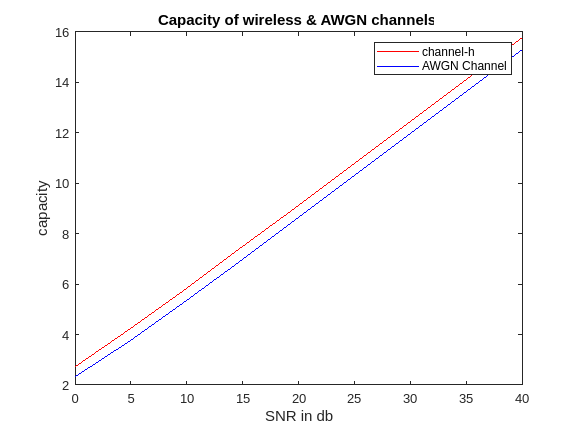

title('Capacity of wireless & AWGN channels ')
xlabel('SNR in db')
ylabel('capacity')
legend("channel-h", "AWGN Channel")

### Q3. Capacity plot for fast-fading SIMO channel:

SNRdb3 = 0:5:40;
SNRlinear3 = 10.^(SNRdb3/10);
%capacity_fastfading = zeros(size(SNRdb3));

expectedCapacity = zeros(1 ,length(SNRdb3));

for i = 1:length(SNRdb3)
    sum = 0;
    %Calculating the capacity for different values of h (representing the
    %fastfading channel) and finding the expectation of them.
    for j = 1:1000
        h3 = (1/sqrt(2))*(randn(4,1) + 1i*randn(4,1)); %dividing by 
        % square root of 2 to make variance equal to 1
        norm_h3_squared = norm(h3)^2;
        sum = sum + log2(1+norm_h3_squared*SNRlinear3(i));
    end

    expectedCapacity(i) = sum/1000;
end

%disp(expectedCapacity)

Plotting the Expected values of capacity versus SNRdb

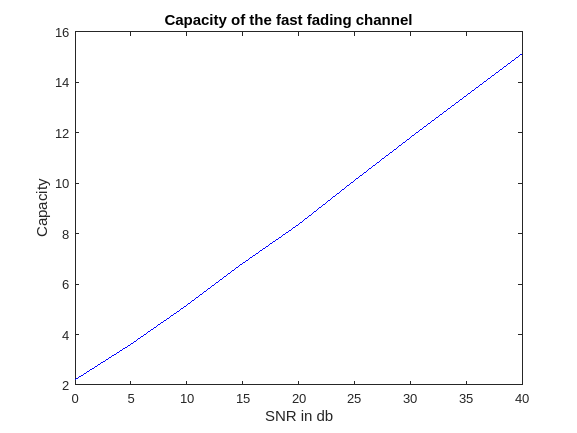

plot(SNRdb3, expectedCapacity, 'b')
title('Capacity of the fast fading channel     ')
xlabel('SNR in db')
ylabel('Capacity')